We return to he equation $u'=\sin[(u+t)^2]$ to see two variations on how to obtain numerical solutions for it. In the first one, we can supply a vector of time nodes and receive the solution at exactly those times. 

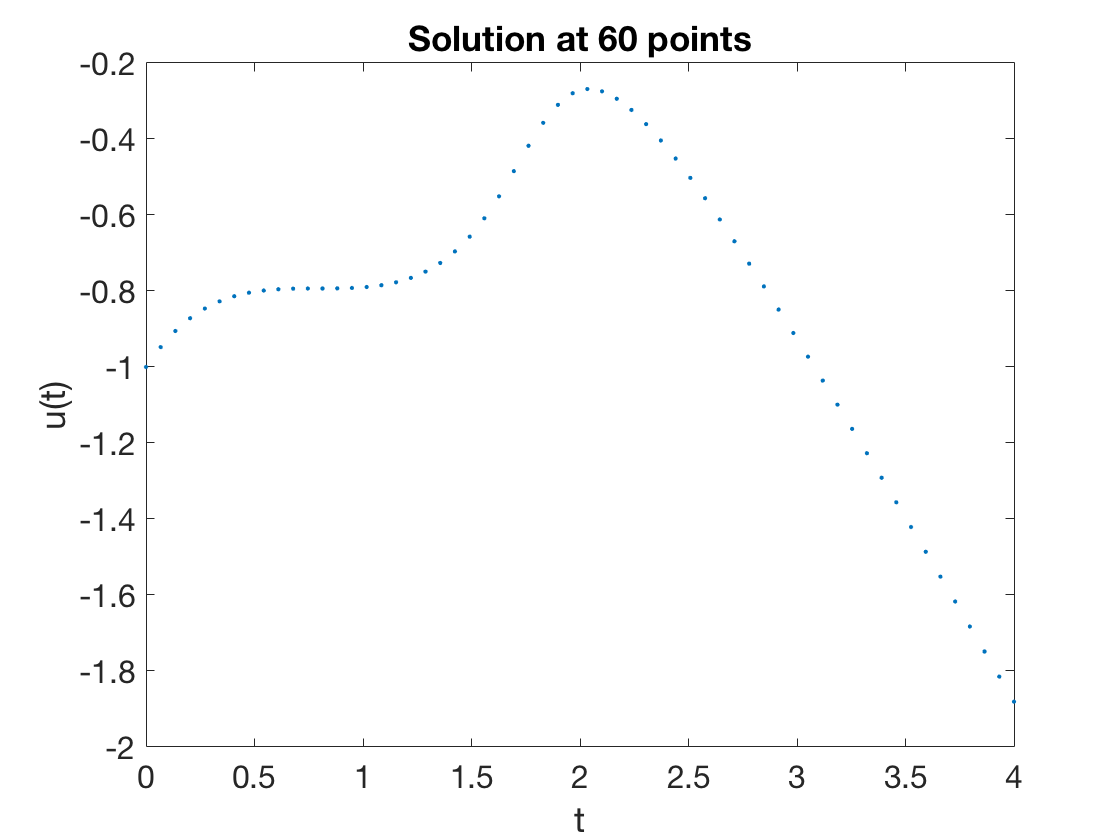

f = @(t,u) sin( (t+u).^2 );
t = linspace(0,4,60)';
[t,u] = ode45(f,t,-1);
plot(t,u,'.')
xlabel('t'), ylabel('u(t)'), title('Solution at 60 points')     % ignore this line

In the second variation, we see that it's also possible to create a callable function for the solution. Essentially this is a high-quality interpolant of the computed particular values. 

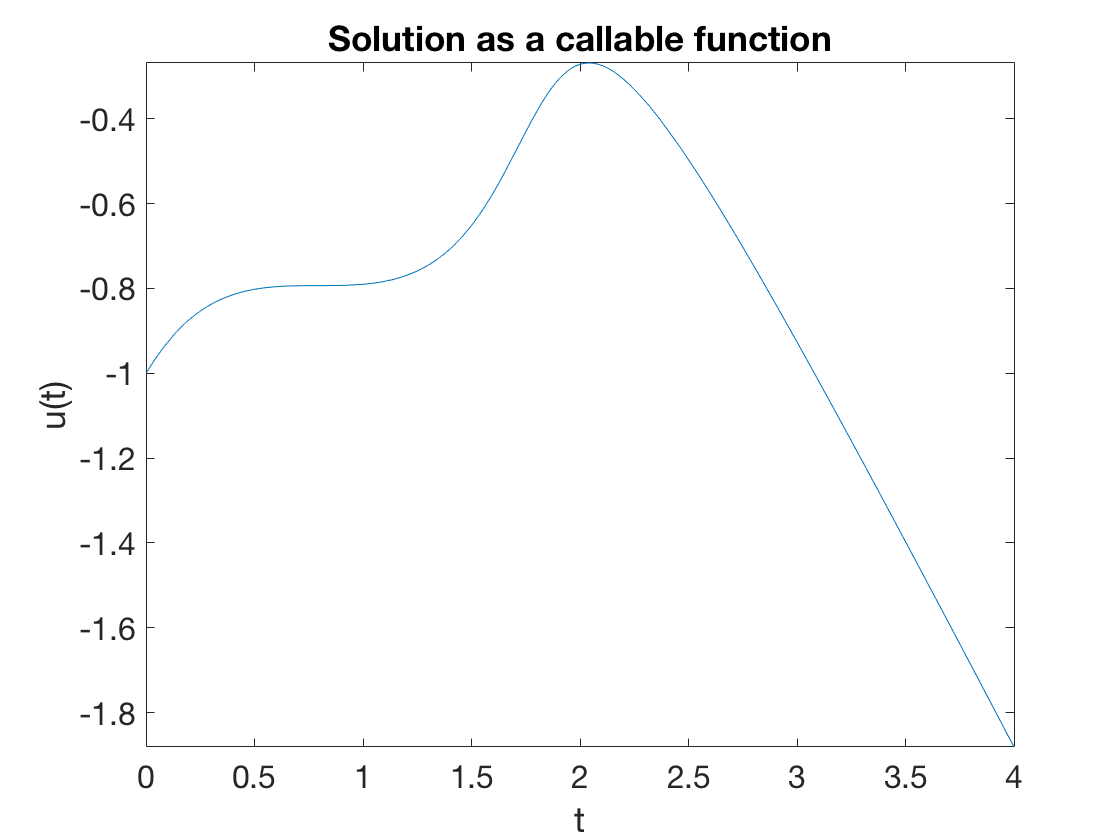

u = @(t) deval( ode45(f,[0,4],-1), t );
fplot(u,[0,4])
xlabel('t'), ylabel('u(t)'), title('Solution as a callable function')     % ignore this line